**Baseband Transmission**

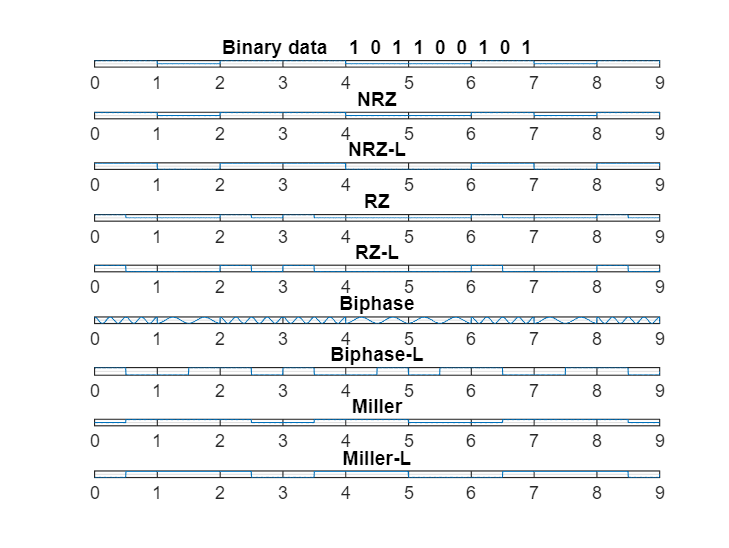

bits = [1 0 1 1 0 0 1 0 1];
bps = 1;

figure;
subplot(9,1,1);
[t1,s1] = displaySignal(bits,bps);
plot(t1,s1);
axis([0 t(end) -1.1 1.1])
grid on;
title(['Binary data    ' num2str(bits) ]);

subplot(9,1,2); 
[t2,s2] = NRZcode(bits,bps);
plot(t2,s2);
axis([0 t(end) -1.1 1.1])
grid on;
title(['NRZ']);


subplot(9,1,3);
[t3,s3] = NRZL(bits,bps);
plot(t3,s3);
axis([0 t(end) -1.1 1.1])
grid on;
title(['NRZ-L']);

subplot(9,1,4);
[t4,s4] = RZcode(bits,bps);
plot(t4,s4);
axis([0 t(end) -1.1 1.1])
grid on;
title(['RZ']);

subplot(9,1,5);
[t5,s5] = RZL(bits,bps);
plot(t5,s5);
axis([0 t(end) -1.1 1.1])
grid on;
title(['RZ-L']);

subplot(9,1,6);
[t6,s6] = BiPhase(bits,bps);
plot(t,s);
axis([0 t(end) -1.1 1.1])
grid on;
title(['Biphase']);

subplot(9,1,7);
[t7,s7] = BiPhaseL(bits,bps);
plot(t7,s7);
axis([0 t(end) -1.1 1.1])
grid on;
title(['Biphase-L']);

subplot(9,1,8);
[t8,s8] = Miller(bits,bps);
plot(t8,s8);
axis([0 t(end) -1.1 1.1])
grid on;
title(['Miller']);

subplot(9,1,9);
[t9,s9] = MillerL(bits,bps);
plot(t9,s9);
axis([0 t(end) -1.1 1.1])
grid on;
title(['Miller-L']);

**Passband Modulation**

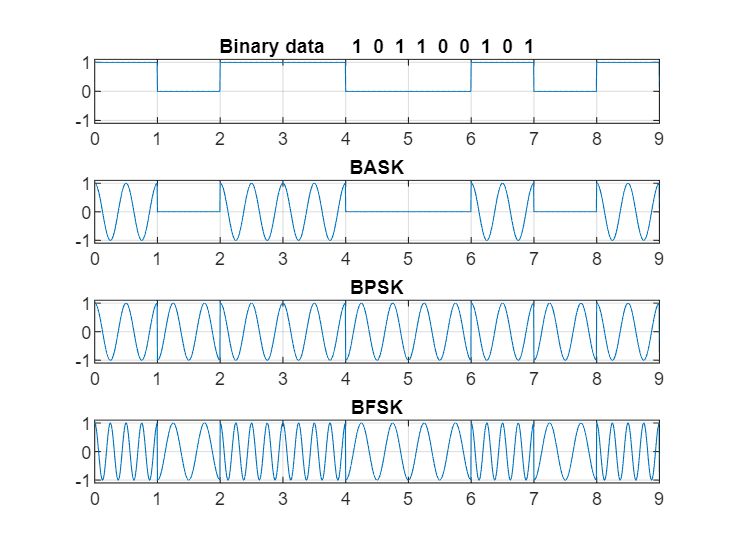

bits = [1 0 1 1 0 0 1 0 1];
bps = 1; % bits per second
figure;
subplot(4,1,1);
[t,s] = displaySignal(bits,bps);
plot(t,s);
axis([0 t(end) -1.1 1.1])
grid on;
title(['Binary data     ' num2str(bits) ]);
subplot(4,1,2);
[t,s] = modBASK(bits,bps);
plot(t,s);
axis([0 t(end) -1.1 1.1])
grid on;
title(['BASK']);
subplot(4,1,3);
[t,s] = modBPSK(bits,bps);
plot(t,s);
axis([0 t(end) -1.1 1.1])
grid on;
title(['BPSK']);
subplot(4,1,4);
[t,s] = modBFSK(bits,bps);
plot(t,s);
axis([0 t(end) -1.1 1.1])
grid on;
title(['BFSK']);

**Functions:**

We want to express our big thanls to 

**displaySignal()**

function [t,x] = displaySignal(bits, bps)
T = length(bits)/bps;
n = 200;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t)); 
for i = 0:length(bits)-1
  if bits(i+1) == 1
    x(i*n+1:(i+1)*n) = 1;
  else
    x(i*n+1:(i+1)*n) = 0;
  end
end
end

 `NRZCode`()

function [t,x] = NRZcode(bits, bps)
T = length(bits)/bps; 
n = 200;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t)); 
for i = 0:length(bits)-1
  if bits(i+1) == 1
    x(i*n+1:(i+1)*n) = 1;
  else
    x(i*n+1:(i+1)*n) = 0;
  end
end
end

`NRZL`()

function [t,x] = NRZL(bits, bps)
T = length(bits)/bps; 
n = 200;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t));
for i = 0:length(bits)-1
  if bits(i+1) == 1
    x(i*n+1:(i+1)*n) = 1;
  else
    x(i*n+1:(i+1)*n) = -1;
  end
end
end

`RZCode`()

function [t,x] = RZcode(bits, bps)
T = length(bits)/bps;
n = 200;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t));
for i = 0:length(bits)-1
  if bits(i+1) == 1
    x(i*n+1:(i+0.5)*n) = 1;
    x((i+0.5)*n+1:(i+1)*n) = 0;
  else
    x(i*n+1:(i+1)*n) = 0;
  end
end
end

`RZL`()

function [t,x] = RZL(bits, bps)
T = length(bits)/bps;
n = 200;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t));
for i = 0:length(bits)-1
  if bits(i+1) == 1
    x(i*n+1:(i+0.5)*n) = 1;
    x((i+0.5)*n+1:(i+1)*n) = -1;
  else
    x(i*n+1:(i+1)*n) = -1;
  end
end
end

 `BiPhase`()

function [t,x] = BiPhase(bits, bps)
T = length(bits)/bps; 
n = 200;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t)); 
for i = 0:length(bits)-1
  if bits(i+1) == 1
    x(i*n+1:(i+0.5)*n) = 1;
    x((i+0.5)*n+1:(i+1)*n) = 0;
  else
    x(i*n+1:(i+0.5)*n) = 0;
    x((i+0.5)*n+1:(i+1)*n) = 1;
  end
end
end

`BiPhaseL`()

function [t,x] = BiPhaseL(bits, bps)
T = length(bits)/bps;
n = 200;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t));
for i = 0:length(bits)-1
  if bits(i+1) == 1
    x(i*n+1:(i+0.5)*n) = 1;
    x((i+0.5)*n+1:(i+1)*n) = -1;
  else
    x(i*n+1:(i+0.5)*n) = -1;
    x((i+0.5)*n+1:(i+1)*n) = 1;
  end
end
end

`Miller`()

function [t,x] = Miller(bits, bps)
T = length(bits)/bps; 
n = 200;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t)); 
if bits(1) == 1
    x(1:0.5*n) = 0;
    x(0.5*n+1:n) =1;
else
    x(1:n) = 0;
end
for i = 1:length(bits)-1
  if bits(i+1) == 1
      if x(i*n) ==1
        x(i*n+1:(i+0.5)*n) = 1;
        x((i+0.5)*n+1:(i+1)*n) = 0;
      else
        x(i*n+1:(i+0.5)*n) = 0;
        x((i+0.5)*n+1:(i+1)*n) = 1;
      end
  else
      if bits(i) == 1
        x(i*n+1:(i+1)*n) = x(i*n);
      else
        x(i*n+1:(i+1)*n) = abs(1-x(i*n));
      end
  end
end
end

`MillerL`()

function [t,x] = MillerL(bits, bps)
T = length(bits)/bps; 
n = 200;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t)); 
if bits(1) == 1
    x(1:0.5*n) = -1;
    x(0.5*n+1:n) =1;
else
    x(1:n) = -1;
end
for i = 1:length(bits)-1
  if bits(i+1) == 1
      if x(i*n) ==1
        x(i*n+1:(i+0.5)*n) = 1;
        x((i+0.5)*n+1:(i+1)*n) = -1;
      else
        x(i*n+1:(i+0.5)*n) = -1;
        x((i+0.5)*n+1:(i+1)*n) = 1;
      end
  else
      if bits(i) == 1
        x(i*n+1:(i+1)*n) = x(i*n);
      else
        x(i*n+1:(i+1)*n) = (-1)*x(i*n);
      end
  end
end
end

`modBASK`(), 

function [t,x] = modBASK(bits, bps)
    [t,x] = displaySignal(bits,bps);
    x = x.*cos(2*2*pi*t);
end

`modBPSK`()

function [t,x] = modBPSK(bits, bps)
    [t,x] = displaySignal(bits,bps);
    x = x.*cos(2*2*pi*t) + (1-x).*cos(2*2*pi*t+pi);
end

`modBFSK`()

function [t,x] = modBFSK(bits, bps)
    [t,x] = displaySignal(bits,bps);
    x = x.*cos(2*4*pi*t) + (1-x).*cos(2*2*pi*t+pi);
end